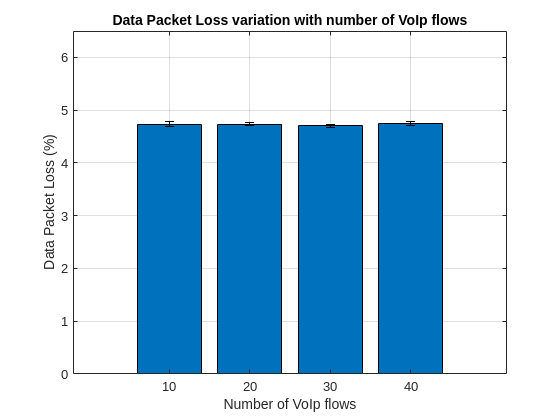

% a

N = 20; % numero de vezes a correr a simulacao

lambda = 1500;  % valor lambda (1500 pps)
alfa = 0.1;     % valor alfa (1 - intervalo confianca)
C = 10;         % capacidade do link (mbps)
f = 1000000;    % tamanho da fila em bytes
P = 100000;     % numero de pacotes processados ate a simulacao parar
b = 10^-5;      % Bit-Error-Rate (ber)
n = [10 20 30 40]; % valores do numero de fluxos de pacotes VoIp a testar

results = zeros(length(n), 7, 2); % matriz para guardar os resultados

for l=1:length(n)
    tmp = zeros(7, N); % matriz temporaria para guardar resultados nao processados

    % correr simulador N vezes e guardar o resultado em tmp
    for i=1:N
        [tmp(1, i), tmp(2, i), tmp(3, i), tmp(4, i), ... 
         tmp(5, i), tmp(6, i), tmp(7, i)] = Simulator3A(lambda, C, f, P, n(l), b);
    end

    % processar resultados e guarda-los
    % results(:, :, 1) contem valores de medias
    % results(:, :, 2) contem os valores do intervalo de confianca
    for i=1:7
        results(l, i, 1) = mean(tmp(i, :));
        results(l, i, 2) = norminv(1-alfa/2)*sqrt(var(tmp(i, :))/N);
    end
end

% Desenhar grafico da perda de pacotes DATA para varios numeros de fluxos
bar(n, results(:, 1, 1));
title("Data Packet Loss variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("Data Packet Loss (%)");
ylim([0 6.5]);
grid on;
hold on;
er = errorbar(n, results(:, 1, 1), results(:, 1, 2), results(:, 1, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

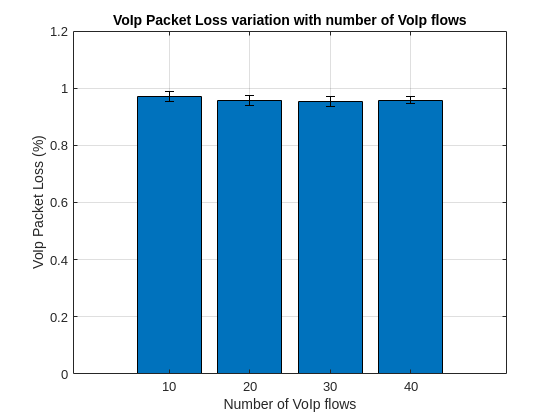


% Desenhar grafico da perda de pacotes VoIp para varios numeros de fluxos
bar(n, results(:, 2, 1));
title("VoIp Packet Loss variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("VoIp Packet Loss (%)");
ylim([0 1.2]);
grid on;
hold on;
er = errorbar(n, results(:, 2, 1), results(:, 2, 2), results(:, 2, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

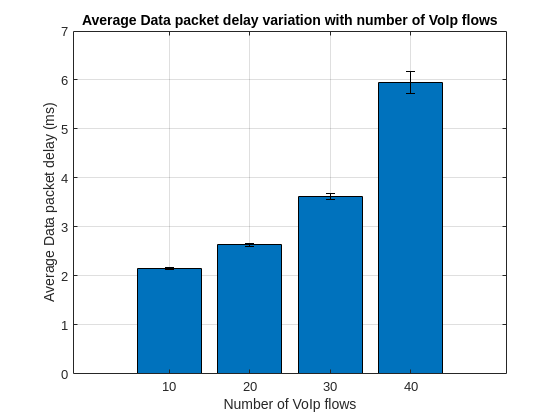


% Desenhar grafico do atraso medio de pacotes DATA para varios numeros de fluxos
bar(n, results(:, 3, 1));
title("Average Data packet delay variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("Average Data packet delay (ms)");
grid on;
hold on;
er = errorbar(n, results(:, 3, 1), results(:, 3, 2), results(:, 3, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

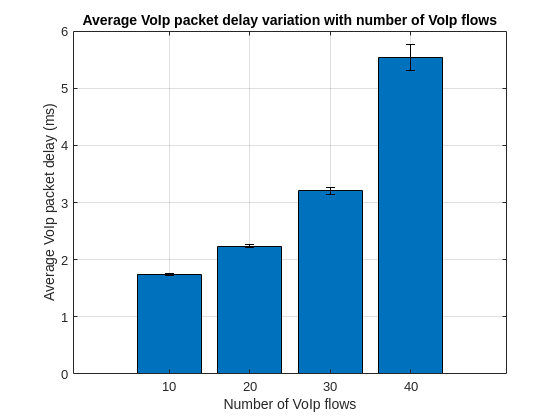


% Desenhar grafico do atraso medio de pacotes VoIp para varios numeros de fluxos
bar(n, results(:, 4, 1));
title("Average VoIp packet delay variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("Average VoIp packet delay (ms)");
grid on;
hold on;
er = errorbar(n, results(:, 4, 1), results(:, 4, 2), results(:, 4, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;